# Q1

clc;
clear; 
close all;
%% Generate Tall-Skinny Matrix A
m = 1701;  % Number of rows (much greater than columns)
n = 4;     % Number of columns
A = randn(m, n);  % Generate a random Tall-Skinny matrix

% Call the TSQR decomposition function
[Q, R] = tsqr(A);

% Verify if Q is an orthogonal matrix
disp("Q Orthogonality Check (Q'*Q):");

Q Orthogonality Check (Q'*Q):


disp(norm(Q'*Q - eye(n), 'fro'));

   7.7853e-16




% Compute reconstruction error to check TSQR correctness
disp("Reconstruction Error (||A - Q*R||_F):");

Reconstruction Error (||A - Q*R||_F):


disp(norm(A - Q*R, 'fro'));

   1.7275e-14



Tall-Skinny QR decomposition, split matrix A into 4 sub-blocks, and perform local QR calculations on each sub-block. Then, the final R_final is calculated by recursively merging R and the global Q_final is constructed to maintain orthogonality. Finally, A = Q_final * R_final reduces the amount of calculation

%% TSQR Main Function
function [Q_final, R_final] = tsqr(A)
    [m, n] = size(A);  % Get the dimensions of matrix A
    num_blocks = 4;  % Divide A into 4 blocks
    block_size = ceil(m / num_blocks);  % Compute block size ensuring uniform size

    % Preallocate storage for local Q and R matrices
    Q_blocks = cell(1, num_blocks);
    R_blocks = cell(1, num_blocks);

    % STEP 1: Perform local QR decomposition for each block
    for i = 1:num_blocks
        start_row = (i-1) * block_size + 1;  % Compute start row index for the current block
        end_row = min(i * block_size, m);  % Compute end row index, ensuring no out-of-bounds access
        A_i = A(start_row:end_row, :);  % Extract the submatrix for the current block
        [Q_i, R_i] = qr(A_i, 0);  % Perform economy QR decomposition
        Q_blocks{i} = Q_i;  % Store local Q
        R_blocks{i} = R_i;  % Store local R
    end

    % STEP 2: Recursively merge R matrices
    [R_final, Q_reduction] = recursive_tsqr(R_blocks, n);

    % STEP 3: Construct the final Q matrix
    Q_big = blkdiag(Q_blocks{:});  % Form a block diagonal matrix combining all local Q
    Q_final = Q_big * Q_reduction;  % Compute the final Q matrix
    Q_final = Q_final(:, 1:n);  % Keep only the first n columns to ensure correct dimensions
end

Recursively merge the R matrix, QR decompose adjacent R each time, generate a new R_new and continue recursively until R_final has only one upper triangle matrix left. Meanwhile, Q_list records Q_combined and finally calculates the global transformation matrix Q_final through the block diagonal matrix blkdiag(Q_list{:}) (I found that for will always have dimension errors).

%% Recursive R Merging Function
function [R_final, Q_final] = recursive_tsqr(R_list, n)
    num_blocks = length(R_list);  % Get the number of R blocks
    
    % Base case: If only one R block remains, return it
    if num_blocks == 1
        R_final = R_list{1};  % Return the final R
        Q_final = eye(size(R_list{1}, 1));  % Initialize Q as an identity matrix
        return;
    end

    % Preallocate new R and Q lists
    new_R_list = cell(1, ceil(num_blocks / 2));
    Q_list = cell(1, ceil(num_blocks / 2));
    
    % Pairwise merge R blocks
    for i = 1:2:num_blocks
        if i+1 <= num_blocks
            stacked_R = [R_list{i}; R_list{i+1}];  % Stack R blocks vertically
            [Q_combined, R_new] = qr(stacked_R, 0);  % Perform QR decomposition on the stacked matrix
            new_R_list{ceil(i/2)} = R_new;  % Store the new R
            Q_list{ceil(i/2)} = Q_combined;  % Store the new Q
        else
            new_R_list{ceil(i/2)} = R_list{i};  % If an R block has no pair, carry it forward
            Q_list{ceil(i/2)} = eye(size(R_list{i}, 1));  % Maintain an identity Q for a single R block
        end
    end

    % Recursively merge the newly generated R blocks
    [R_final, Q_child] = recursive_tsqr(new_R_list, n);
    
    % Compute the final Q matrix by combining the current level Q with Q_child
    Q_final = blkdiag(Q_list{:}) * Q_child;
    Q_final = Q_final(:, 1:size(R_final, 2));  % Adjust dimensions to match R_final
end

# Q3

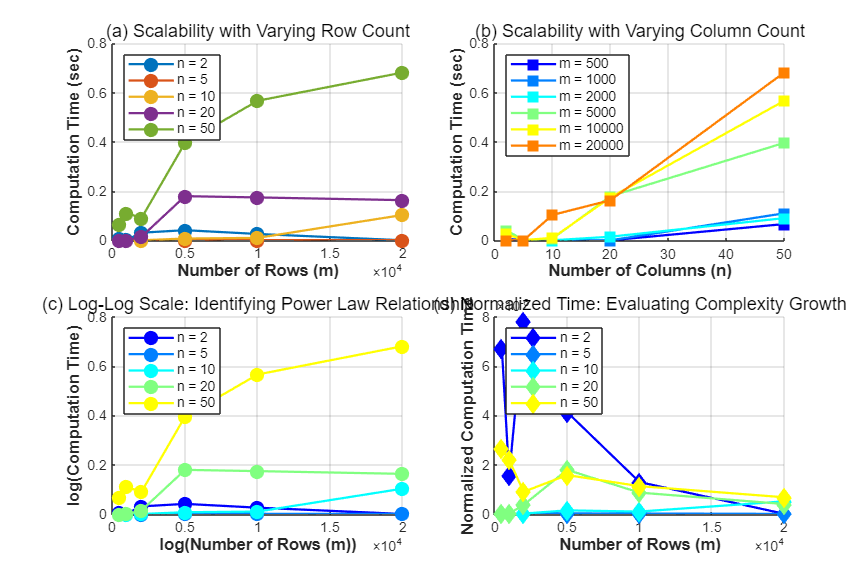

%% Data Preprocessing
clc; clear;
opts = detectImportOptions('scaling_results.csv');  % Detect import options for CSV file
opts.VariableNamingRule = 'preserve';  % Preserve original variable names
data = readtable('scaling_results.csv', opts);  % Read CSV file into a table

% Sort data based on 'm' values in ascending order
[~, idx] = sort(data.m);
data = data(idx, :);

%% Plot Scalability Charts
figure('Position', [100 100 1200 800], 'Color','w')  % Set figure size and background color

% ========== Subplot 1: Effect of m while keeping n fixed ==========
subplot(2,2,1)  % Create the first subplot
hold on; grid on;
n_values = unique(data.n);  % Get unique values of n
colors = lines(length(n_values));  % Generate distinct colors for different n values

for i = 1:length(n_values)
    mask = (data.n == n_values(i));  % Select rows where n matches the current value
    plot(data.m(mask), data.("time(sec)")(mask),...  % Plot computation time against m
        'o-', 'LineWidth',1.5, 'MarkerSize',8,...
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...
        'DisplayName', sprintf('n = %d', n_values(i)))
end

xlabel('Number of Rows (m)', 'FontSize', 11, 'FontWeight', 'bold')
ylabel('Computation Time (sec)', 'FontSize', 11, 'FontWeight', 'bold')
title('(a) Scalability with Varying Row Count', 'FontSize', 12)
legend('Location','northwest', 'FontSize', 9)

% ========== Subplot 2: Effect of n while keeping m fixed ==========
subplot(2,2,2)  % Create the second subplot
hold on; grid on;
m_values = unique(data.m);  % Get unique values of m
colors = jet(length(m_values));  % Generate distinct colors for different m values

for i = 1:length(m_values)
    mask = (data.m == m_values(i));
    plot(data.n(mask), data.("time(sec)")(mask),...
        's-', 'LineWidth',1.5, 'MarkerSize',8,...
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...
        'DisplayName', sprintf('m = %d', m_values(i)))
end

xlabel('Number of Columns (n)', 'FontSize', 11, 'FontWeight', 'bold')
ylabel('Computation Time (sec)', 'FontSize', 11, 'FontWeight', 'bold')
title('(b) Scalability with Varying Column Count', 'FontSize', 12)
legend('Location','northwest', 'FontSize', 9)

%% Additional Analysis Plots

% ========== Subplot 3: Log-Log Scale Analysis ==========
subplot(2,2,3)  
hold on; grid on;

for i = 1:length(n_values)
    mask = (data.n == n_values(i));
    loglog(data.m(mask), data.("time(sec)")(mask),...
        'o-', 'LineWidth',1.5, 'MarkerSize',8,...
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...
        'DisplayName', sprintf('n = %d', n_values(i)))
end

xlabel('log(Number of Rows (m))', 'FontSize', 11, 'FontWeight', 'bold')
ylabel('log(Computation Time)', 'FontSize', 11, 'FontWeight', 'bold')
title('(c) Log-Log Scale: Identifying Power Law Relationship', 'FontSize', 12)
legend('Location','northwest', 'FontSize', 9)

% ========== Subplot 4: Normalized Computation Time ==========
subplot(2,2,4)  
hold on; grid on;

for i = 1:length(n_values)
    mask = (data.n == n_values(i));
    norm_time = data.("time(sec)")(mask) ./ (data.m(mask) .* data.n(mask)); % Normalize by problem size
    plot(data.m(mask), norm_time,...
        'd-', 'LineWidth',1.5, 'MarkerSize',8,...
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...
        'DisplayName', sprintf('n = %d', n_values(i)))
end

xlabel('Number of Rows (m)', 'FontSize', 11, 'FontWeight', 'bold')
ylabel('Normalized Computation Time', 'FontSize', 11, 'FontWeight', 'bold')
title('(d) Normalized Time: Evaluating Complexity Growth', 'FontSize', 12)
legend('Location','northwest', 'FontSize', 9)

%% Save Figure
print -dpng -r300 scaling_analysis.png  % Save the figure as a high-resolution PNG file

disp('Figure saved as scaling_analysis.png')

Figure saved as scaling_analysis.png


Using an m × n dimensional random matrix, TSQR computes the QR decomposition in parallel through MPI and records the calculation time. The left figure shows the trend of the calculation time changing with m when the n is fixed. It can be seen that the increase in the number of rows will affect the calculation time, but the growth rate varies from n. The figure on the right shows the calculation time changes with n when the m is fixed, indicating that larger m will cause the calculation cost to rise faster when n grows. Overall, TSQR is more sensitive to m, while the influence of n is more obvious when larger m is, which conforms to the computational characteristics of the Tall-Skinny structure

(c) Log-Log Scale chart shows that calculation time may have a power-law growth trend for m, but the data fluctuates and may be affected by n and MPI computational communications.

(d) Normalized calculation time indicates that the TSQR calculation complexity is close to O(mn), that is, the calculation time basically increases linearly with the increase of m and n.